clc
clear

POINTS = 50;

C = [3, 1; -1, -2];

x = linprog([2; -1], [0, 1; 3, -1], [3; 6], [], [], [0; 0])


Optimal solution found.



x =      0
     3


p = C*x

p =      3
    -6


syms f(x)
f(x) = -x+sum(p)

$$f(x) = -x-3$$

min_c1= linprog(C(1, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0]);


Optimal solution found.



min_c2 = linprog(C(2, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0]);


Optimal solution found.



most_left = C*min_c1

most_left =      0
     0


most_right = C*min_c2

most_right =     12
    -9


select = linspace(-3, 13, POINTS);
q = double([select; f(select)]);

front = zeros(2, size(q, 2));
solution = zeros(3, size(q, 2));
for i = 1:size(q, 2)
    solution(:, i) = linprog([0, 0, 1], [C, [-1; -1]; [0, 1, 0; 3, -1, 0]],...
                             [q(:,i); 3; 6], [], [], [0; 0; 0]);
    front(:,i) = q(:,i) + solution(3, i)*[1; 1];      
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

front

front =          0         0         0   -0.0000         0    0.0884    0.3061    0.5238    0.7415    0.9592    1.1769    1.3946    1.6122    1.8299    2.0476    2.2653    2.4830    2.7007    2.9184    3.3061    3.7959    4.2857    4.7755    5.2653    5.7551    6.2449    6.7347    7.2245    7.7143    8.2041    8.6939    9.1837    9.6735   10.1633   10.6531   11.1429   11.6327   12.1633   12.8163   13.4694   14.1224   14.7755   15.4286   16.0816   16.7347   17.3878   18.0408   18.6939   19.3469   20.0000
    3.0000    2.3469    1.6939    1.0408    0.3878   -0.1769   -0.6122   -1.0476   -1.4830   -1.9184   -2.3537   -2.7891   -3.2245   -3.6599   -4.0952   -4.5306   -4.9660   -5.4014   -5.8367   -6.1020   -6.2653   -6.4286   -6.5918   -6.7551   -6.9184   -7.0816   -7.2449   -7.4082   -7.5714   -7.7347   -7.8980   -8.0612   -8.2245   -8.3878   -8.5510   -8.7143   -8.8776   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000 

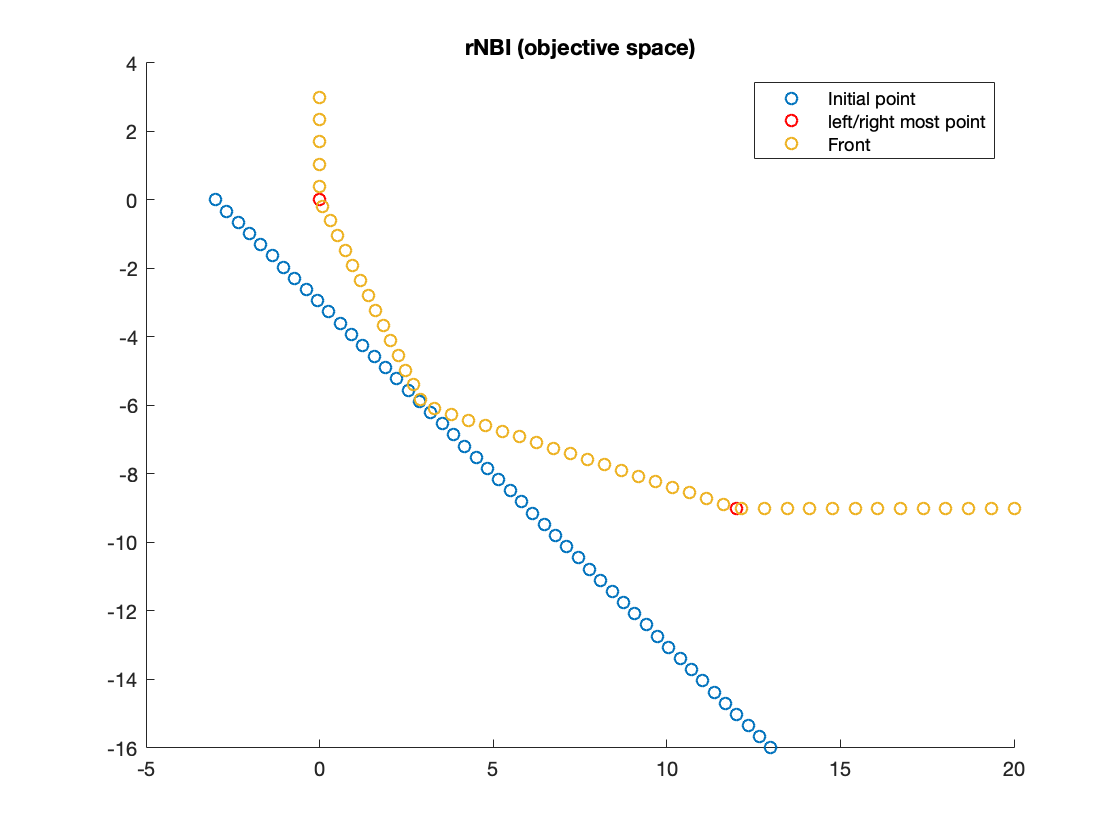

scatter(q(1,:), q(2,:));
hold on
scatter([0, 12], [0, -9], 'red');
scatter(front(1,:), front(2, :))
title('rNBI (objective space)');
legend({'Initial point','left/right most point','Front'})